Aproximare prin **Metoda Celor Mai Mici Patrate**

Avem datele de antrenament, reprezentand:

- x - caracteristicile datelor de antrenament;

- y - output-ul unei anumite functii in caracteristicile x;

Dorim sa aproximam cat de bine se poate functia


$$f(x) = a_0 * \phi_0(x) + a_1 * \phi_1(x) + ... + a_n * \phi_k(x)$$


pentru a obtine valori cat mai apropiate de datele de test pe care dorim sa le obtinem (o aproximare foarte apropiata).

Astfel, task-ul se reduce la minimizarea

$\sum_{i=1}^{n}{w_i * (y_i - y_i^{approx})^2}$, unde:

- w - vectorul weight-urilor, care influenteaza fiecare caracteristica in parte

- y - output-ul adevarat;

- y^approx - output-ul aproximat.

In esenta, dorim sa **minimizam eroarea de aproximare** dintre output-ul adevarat si output-ul de aproximat.

Avand n puncte $(x_1, x_2, \dots, x_n)$ si valorile lor prin functia f $(f(x_1)=y_1, f(x_2)=y_2, \dots, f(x_n)=y_n)$, problema se reduce la calcularea:

$(Phi * W * Phi^T) * a = Phi * W * y$, unde:

- Phi = $\left\lbrack \begin{array}{ccccc}
a_0  & a_1 *x_0  & a_2 *x_0^2  & \cdots  & a_n *x_0^n \\
a_0  & a_1 *x_1  & a_2 *x_1^2  & \cdots  & a_n *x_1^n \\
a_0  & a_1 *x_2  & a_2 *x_2^2  & \cdots  & a_n *x_2^n \\
\vdots  & \ddots  & \ddots  & \ddots  & \vdots \\
a_0  & a_1 *x_n  & a_2 *x_n^2  & \cdots  & a_n *x_n^n 
\end{array}\right\rbrack$, care reprezinta matricea formata din solutiile in fiecare punct din x;

- W = $\left\lbrack \begin{array}{ccccc}
w_0  & 0 & 0 & \cdots  & 0\\
0 & w_1  & 0 & \cdots  & 0\\
0 & 0 & w_2  & \cdots  & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & \vdots \\
0 & 0 & 0 & \cdots  & w_n 
\end{array}\right\rbrack$, care reprezinta matricea diagonala formata din weight-urile calculate. In modul asta, fiecare weight va afecta efectiv fiecare caracteristica in parte, nu tot sistemul; vrem sa vedem comportamentul in perturbarea fiecarui termen.

Astfel, daca notam $A = Phi * W * Phi^T$ si $B = Phi * W * y$, putem determina coeficientii noi $a = A^{-1} * B$, iar apoi valorile aproximate $y^{approx} = a^T * Phi^{approx}$.

x = 1:20;
y = sin(x);

base = poly_base(10);

y_approx = least_squares(x, y, base, x);

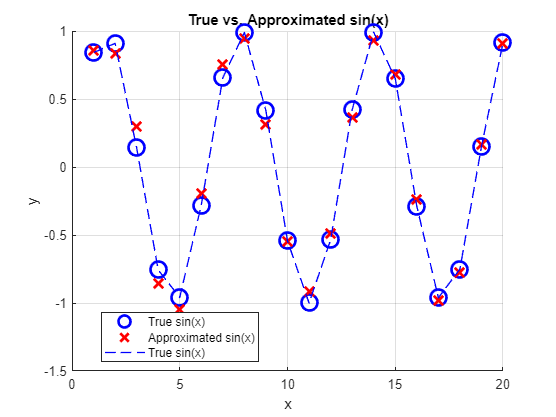

figure;
hold on;

grid on;
plot(x, y, 'bo', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'True sin(x)');
plot(x, y_approx, 'rx', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Approximated sin(x)');
plot(x, y, 'b--', 'LineWidth', 1, 'DisplayName', 'True sin(x)');

title('True vs. Approximated sin(x)');
legend('Location','best');
xlabel('x');
ylabel('y');

hold off;